## PD energy rescue

The SYNAPTIC PD model

%% SYNAPTIC PARKINSON'S DISEASE model_SYNPD
method = 'eFBA';
model_SYNPD = SYNPD;
% energy rescue for mito and glycolysis
indATPS4mi = findRxnIDs(model_SYNPD, 'ATPS4mi');
indPYK = findRxnIDs(model_SYNPD, 'PYK');
indPGK = findRxnIDs(model_SYNPD, 'PGK');
% too much rxns if we only use above three rxns
indGLC = findRxnIDs(model_SYNPD, 'EX_glc_D[e]');
indO2 = findRxnIDs(model_SYNPD, 'EX_o2[e]');
indDopa = findRxnIDs(model_SYNPD, 'EX_dopa[e]');
indMet = findRxnIDs(model_SYNPD, 'EX_met_L[e]');
indGln = findRxnIDs(model_SYNPD, 'EX_gln_L[e]');
indLys = findRxnIDs(model_SYNPD, 'EX_lys_L[e]');
indHis = findRxnIDs(model_SYNPD, 'EX_his_L[e]');
indLac= findRxnIDs(model_SYNPD, 'EX_lac_L[e]');
indUrea = findRxnIDs(model_SYNPD, 'EX_urea[e]');
ind4mop = findRxnIDs(model_SYNPD, 'EX_4mop[e]');
% single reactiond delection
hasEffect_SYNPD = [];
% with different ATPM value
ATPMvalue = 10.62;
for i = 1:length(model_SYNPD.rxns)
    showprogress(0, 'Single reaction deletion analysis in progress ...');
    model_SYNPD = SYNPD;
    model_SYNPD = changeObjective(model_SYNPD, 'ATPM');
    model_SYNPD = changeRxnBounds(model_SYNPD, 'ATPM', ATPMvalue, 'l');
    model_SYNPD = changeRxnBounds(model_SYNPD, model_SYNPD.rxns(i), 0, 'b');
    switch method
        case 'FBA'
            FBAsolution = optimizeCbModel(model_SYNPD, 'max', 1e-6);
        case 'eFBA'
            param.debug = 1;
            try
                FBAsolution=entropicFluxBalanceAnalysis(model_SYNPD,param);
                hasEffect_SYNPD(i,1) = FBAsolution.v(indATPS4mi);
                hasEffect_SYNPD(i,2) = FBAsolution.v(indPYK);
                hasEffect_SYNPD(i,3) = FBAsolution.v(indPGK);
                hasEffect_SYNPD(i,4) = FBAsolution.v(indGLC);
                hasEffect_SYNPD(i,5) = FBAsolution.v(indO2);
                hasEffect_SYNPD(i,6) = FBAsolution.v(indDopa);
                hasEffect_SYNPD(i,7) = FBAsolution.v(indMet);
                hasEffect_SYNPD(i,8) = FBAsolution.v(indGln);
                hasEffect_SYNPD(i,9) = FBAsolution.v(indLys);
                hasEffect_SYNPD(i,10) = FBAsolution.v(indHis);
                hasEffect_SYNPD(i,11) = FBAsolution.v(indLac);
                hasEffect_SYNPD(i,12) = FBAsolution.v(indUrea);
                hasEffect_SYNPD(i,13) = FBAsolution.v(ind4mop);
            catch
                hasEffect_SYNPD(i,1) = 0;
                hasEffect_SYNPD(i,2) = 0;
                hasEffect_SYNPD(i,3) = 0;
                hasEffect_SYNPD(i,4) = 0;
                hasEffect_SYNPD(i,5) = 0;
                hasEffect_SYNPD(i,6) = 0;
                hasEffect_SYNPD(i,7) = 0;
                hasEffect_SYNPD(i,8) = 0;
                hasEffect_SYNPD(i,9) = 0;
                hasEffect_SYNPD(i,10) = 0;
                hasEffect_SYNPD(i,11) = 0;
                hasEffect_SYNPD(i,12) = 0;
                hasEffect_SYNPD(i,13) = 0;
            end
    end
end

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2945
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2948
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

Single reaction deletion analysis in progress ...


Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 


tableSYNPD = table(SYNPD.rxns, hasEffect_SYNPD);
tableSYNPD_results = [tableSYNPD(:,1:1),table(tableSYNPD.Var2(:,1),...
    'VariableNames',{'ATPS4mi'}),table(tableSYNPD.Var2(:,2),...
    'VariableNames',{'PYK'}),table(tableSYNPD.Var2(:,3),...
    'VariableNames',{'PGK'}),table(tableSYNPD.Var2(:,4),...
    'VariableNames',{'EX_glucose'}), table(tableSYNPD.Var2(:,5),...
    'VariableNames',{'EX_oxygen'}),table(tableSYNPD.Var2(:,6),...
    'VariableNames',{'EX_dopa'}),table(tableSYNPD.Var2(:,7),...
    'VariableNames',{'EX_met_L[e]'}),table(tableSYNPD.Var2(:,8),...
    'VariableNames',{'EX_gln_L[e]'}),table(tableSYNPD.Var2(:,9),...
    'VariableNames',{'EX_lys_L[e]'}),table(tableSYNPD.Var2(:,10),...
    'VariableNames',{'EX_his_L[e]'}),table(tableSYNPD.Var2(:,11),...
    'VariableNames',{'EX_lac_L[e]'}),table(tableSYNPD.Var2(:,12),...
    'VariableNames',{'EX_urea[e]'}),table(tableSYNPD.Var2(:,13),...
    'VariableNames',{'EX_4mop[e]'})];
%
% writetable(tableSYNPD_results,'~/drive/bioenergeticsPD/results/analysis/PDenergyRescue/EffectRxnsAll_SYNPD.xlsx');

%% compare SYN ATP contribution with the results of single reaction deletion
d=[10.62,30,60];
model_SYN = SYN;
% energy rescue for mito and glycolysis
indATPS4mi = findRxnIDs(model_SYN, 'ATPS4mi');
indPYK = findRxnIDs(model_SYN, 'PYK');
indPGK = findRxnIDs(model_SYN, 'PGK');
% too much rxns if we only use above three rxns
indGLC = findRxnIDs(model_SYN, 'EX_glc_D[e]');
indO2 = findRxnIDs(model_SYN, 'EX_o2[e]');
indDopa = findRxnIDs(model_SYN, 'EX_dopa[e]');
indMet = findRxnIDs(model_SYN, 'EX_met_L[e]');
indGln = findRxnIDs(model_SYN, 'EX_gln_L[e]');
indLys = findRxnIDs(model_SYN, 'EX_lys_L[e]');
indHis = findRxnIDs(model_SYN, 'EX_his_L[e]');
indLac= findRxnIDs(model_SYN, 'EX_lac_L[e]');
indUrea = findRxnIDs(model_SYN, 'EX_urea[e]');
ind4mop = findRxnIDs(model_SYNPD, 'EX_4mop[e]');
for k=1:length(d)
    method = 'eFBA';
    model_SYN = SYN;
    demand = d(1,k);
    model_SYN = changeRxnBounds(model_SYN, 'ATPM', demand, 'b');
    switch method
        case 'FBA'
            FBAsolution = optimizeCbModel(model_SYN, 'max', 1e-6);
        case 'eFBA'
            param.debug = 1;
            try
                FBAsolution=entropicFluxBalanceAnalysis(model_SYN,param);
                SYNflux(k,1) = FBAsolution.v(indATPS4mi);
                SYNflux(k,2) = FBAsolution.v(indPYK);
                SYNflux(k,3) = FBAsolution.v(indPGK);
                SYNflux(k,4) = FBAsolution.v(indGLC);
                SYNflux(k,5) = FBAsolution.v(indO2);
                SYNflux(k,6) = FBAsolution.v(indDopa);
                SYNflux(k,7) = FBAsolution.v(indMet);
                SYNflux(k,8) = FBAsolution.v(indGln);
                SYNflux(k,9) = FBAsolution.v(indLys);
                SYNflux(k,10) = FBAsolution.v(indHis);
                SYNflux(k,11) = FBAsolution.v(indLac);
                SYNflux(k,12) = FBAsolution.v(indUrea);
                SYNflux(k,13) = FBAsolution.v(ind4mop);
            catch
                SYNflux(k,1) = 0;
                SYNflux(k,2) = 0;
                SYNflux(k,3) = 0;
                SYNflux(k,4) = 0;
                SYNflux(k,5) = 0;
                SYNflux(k,6) = 0;
                SYNflux(k,7) = 0;
                SYNflux(k,8) = 0;
                SYNflux(k,9) = 0;
                SYNflux(k,10) = 0;
                SYNflux(k,11) = 0;
                SYNflux(k,12) = 0;
                SYNflux(k,13) = 0;
            end
    end
end

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries 

%% control flux value
ATPSYNvalue = SYNflux(1,1);
PYKSYNvalue = SYNflux(1,2);
PGKSYNvalue = SYNflux(1,3);
EffectRxn1 = [];
EffectRxns1 = [];
for i=1:size(tableSYNPD_results,1)
    ATPnewPD = tableSYNPD_results{i,2};
    PYKnewPD = tableSYNPD_results{i,3};
    PGKnewPD = abs(tableSYNPD_results{i,4});
    DopanewPD =  tableSYNPD_results{i,7}; % original PD flux
    MetnewPD =  tableSYNPD_results{i,8}; % original PD flux
    GlnnewPD =  tableSYNPD_results{i,9}; % original PD flux
    LysnewPD =  tableSYNPD_results{i,10}; % original PD flux
    UreanewPD =  tableSYNPD_results{i,13}; % original PD flux
    LacnewPD =  tableSYNPD_results{i,12}; % original PD flux
    if (ATPnewPD >= ATPSYNvalue) & (PGKnewPD >= PGKSYNvalue) & (PYKnewPD >= PYKSYNvalue) ...
            %& (DopanewPD >= 0.384) & (LysnewPD <= -14.9391) & (UreanewPD >= 0.1597) & (LacnewPD <= -0.2427) %& (MetnewPD <=-1.89) & (GlnnewPD <= -16.6238) &
        EffectRxn1=tableSYNPD_results(i,:);
        EffectRxns1 = [EffectRxns1;EffectRxn1];
    end
end
% printRxnFormula(SYNPD,EffectRxns1{:,1});

2OXOADPTm	akg[m] + 2oxoadp[c] 	<=>	akg[c] + 2oxoadp[m] 
34HPLFM	h[m] + nadh[m] + 34hpp[m] 	->	nad[m] + 34hpl[m] 
AASAD3m	h2o[m] + nad[m] + L2aadp6sa[m] 	->	2 h[m] + L2aadp[m] + nadh[m] 
AKGDm	akg[m] + nad[m] + coa[m] 	->	nadh[m] + co2[m] + succoa[m] 
ASPTAm	akg[m] + asp_L[m] 	<=>	glu_L[m] + oaa[m] 
CO2tm	co2[c] 	<=>	co2[m] 
EX_Rtotal[e]	Rtotal[e] 	->	
EX_Rtotal2[e]	Rtotal2[e] 	->	
LPASE	h2o[c] + lpchol_hs[c] 	->	h[c] + Rtotal[c] + g3pc[c] 
PHETA1m	akg[m] + phe_L[m] 	<=>	glu_L[m] + phpyr[m] 
PSSA1_hs	ser_L[c] + pchol_hs[c] 	<=>	chol[c] + ps_hs[c] 
RTOTAL2t	Rtotal2[e] 	<=>	Rtotal2[c] 
RTOTALt	Rtotal[e] 	<=>	Rtotal[c] 
SACCD3m	h[m] + nadph[m] + akg[m] + lys_L[m] 	->	h2o[m] + nadp[m] + saccrp_L[m] 
THBPT4ACAMDASE	thbpt4acam[c] 	->	h2o[c] + dhbpt[c] 
TYRTAm	akg[m] + tyr_L[m] 	<=>	34hpp[m] + glu_L[m] 
r0074	h2o[m] + nad[m] + glu5sa[m] 	<=>	2 h[m] + nadh[m] + glu_L[m] 
r0085	h2o[c] + HC00591[c] 	->	nh4[c] + akg[c] 
r0156	pyr[c] + gln_L[c] 	->	ala_L[c] + HC00591[c] 
r0450	L2aadp[m] + akg[m] 	<

EffectRxns1.Properties.VariableNames{1}='Bioenergetic rescue reactions';
% writetable(EffectRxns1,'~/drive/bioenergeticsPD/results/analysis/PDenergyRescue/EffectRxns_SYNPD.xlsx');

NON-SYNAPTIC PD

%% NON-SYNAPTIC PARKINSON'S DISEASE model_ASYNPD
model_ASYNPD = ASYNPD;
% energy rescue for mito and glycolysis
indATPS4mi = findRxnIDs(model_ASYNPD, 'ATPS4mi');
indPYK = findRxnIDs(model_ASYNPD, 'PYK');
indPGK = findRxnIDs(model_ASYNPD, 'PGK');
% too much rxns if we only use above three rxns
indGLC = findRxnIDs(model_ASYNPD, 'EX_glc_D[e]');
indO2 = findRxnIDs(model_ASYNPD, 'EX_o2[e]');
indDopa = findRxnIDs(model_ASYNPD, 'EX_dopa[e]');
indMet = findRxnIDs(model_ASYNPD, 'EX_met_L[e]');
indGln = findRxnIDs(model_ASYNPD, 'EX_gln_L[e]');
indLys = findRxnIDs(model_ASYNPD, 'EX_lys_L[e]');
indHis = findRxnIDs(model_ASYNPD, 'EX_his_L[e]');
indLac= findRxnIDs(model_ASYNPD, 'EX_lac_L[e]');
indUrea = findRxnIDs(model_ASYNPD, 'EX_urea[e]');
indGlyc=findRxnIDs(model_ASYNPD,'EX_glyc_R[e]');

% single reactiond delection
hasEffect_ASYNPD = [];
% with different ATPM value
ATPMvalue = 10.62;
for i = 1:length(model_ASYNPD.rxns)
    showprogress(0, 'Single reaction deletion analysis in progress ...');
    model_ASYNPD = ASYNPD;
    model_ASYNPD = changeObjective(model_ASYNPD, 'ATPM');
    model_ASYNPD = changeRxnBounds(model_ASYNPD, 'ATPM', ATPMvalue, 'l');
    model_ASYNPD = changeRxnBounds(model_ASYNPD, model_ASYNPD.rxns(i), 0, 'b');
    switch method
        case 'FBA'
            FBAsolution = optimizeCbModel(model_ASYNPD, 'max', 1e-6);
        case 'eFBA'
            param.debug = 1;
            try
                FBAsolution=entropicFluxBalanceAnalysis(model_ASYNPD,param);
                hasEffect_ASYNPD(i,1) = FBAsolution.v(indATPS4mi);
                hasEffect_ASYNPD(i,2) = FBAsolution.v(indPYK);
                hasEffect_ASYNPD(i,3) = FBAsolution.v(indPGK);
                hasEffect_ASYNPD(i,4) = FBAsolution.v(indGLC);
                hasEffect_ASYNPD(i,5) = FBAsolution.v(indO2);
                hasEffect_ASYNPD(i,6) = FBAsolution.v(indDopa);
                hasEffect_ASYNPD(i,7) = FBAsolution.v(indMet);
                hasEffect_ASYNPD(i,8) = FBAsolution.v(indGln);
                hasEffect_ASYNPD(i,9) = FBAsolution.v(indLys);
                hasEffect_ASYNPD(i,10) = FBAsolution.v(indHis);
                hasEffect_ASYNPD(i,11) = FBAsolution.v(indLac);
                hasEffect_ASYNPD(i,12) = FBAsolution.v(indUrea);
                hasEffect_ASYNPD(i,13) = FBAsolution.v(indGlyc);
            catch
                hasEffect_ASYNPD(i,1) = 0;
                hasEffect_ASYNPD(i,2) = 0;
                hasEffect_ASYNPD(i,3) = 0;
                hasEffect_ASYNPD(i,4) = 0;
                hasEffect_ASYNPD(i,5) = 0;
                hasEffect_ASYNPD(i,6) = 0;
                hasEffect_ASYNPD(i,7) = 0;
                hasEffect_ASYNPD(i,8) = 0;
                hasEffect_ASYNPD(i,9) = 0;
                hasEffect_ASYNPD(i,10) = 0;
                hasEffect_ASYNPD(i,11) = 0;
                hasEffect_ASYNPD(i,12) = 0;
                hasEffect_ASYNPD(i,13) = 0;
            end
    end
end

tableASYNPD = table(ASYNPD.rxns, hasEffect_ASYNPD);
tableASYNPD_results = [tableASYNPD(:,1:1),table(tableASYNPD.Var2(:,1),...
    'VariableNames',{'ATPS4mi'}),table(tableASYNPD.Var2(:,2),...
    'VariableNames',{'PYK'}),table(tableASYNPD.Var2(:,3),...
    'VariableNames',{'PGK'}),table(tableASYNPD.Var2(:,4),...
    'VariableNames',{'EX_glucose'}), table(tableASYNPD.Var2(:,5),...
    'VariableNames',{'EX_oxygen'}),table(tableASYNPD.Var2(:,6),...
    'VariableNames',{'EX_dopa'}),table(tableASYNPD.Var2(:,7),...
    'VariableNames',{'EX_met_L[e]'}),table(tableASYNPD.Var2(:,8),...
    'VariableNames',{'EX_gln_L[e]'}),table(tableASYNPD.Var2(:,9),...
    'VariableNames',{'EX_lys_L[e]'}),table(tableASYNPD.Var2(:,10),...
    'VariableNames',{'EX_his_L[e]'}),table(tableASYNPD.Var2(:,11),...
    'VariableNames',{'EX_lac_L[e]'}),table(tableASYNPD.Var2(:,12),...
    'VariableNames',{'EX_urea[e]'}),table(tableASYNPD.Var2(:,13),...
    'VariableNames',{'EX_glyc[e]'})];
%
writetable(tableASYNPD_results,'~/drive/bioenergeticsPD/fromXi/results/analysis/PDenergyRescue/EffectRxnsAll_ASYNPD.xlsx');

%% compare ASYN ATP contribution with the results of single reaction deletion
d=[10.62,30,60];
model_ASYN = ASYN;
% energy rescue for mito and glycolysis
indATPS4mi = findRxnIDs(model_ASYN, 'ATPS4mi');
indPYK = findRxnIDs(model_ASYN, 'PYK');
indPGK = findRxnIDs(model_ASYN, 'PGK');
% too much rxns if we only use above three rxns
indGLC = findRxnIDs(model_ASYN, 'EX_glc_D[e]');
indO2 = findRxnIDs(model_ASYN, 'EX_o2[e]');
indDopa = findRxnIDs(model_ASYN, 'EX_dopa[e]');
indMet = findRxnIDs(model_ASYN, 'EX_met_L[e]');
indGln = findRxnIDs(model_ASYN, 'EX_gln_L[e]');
indLys = findRxnIDs(model_ASYN, 'EX_lys_L[e]');
indHis = findRxnIDs(model_ASYN, 'EX_his_L[e]');
indLac= findRxnIDs(model_ASYN, 'EX_lac_L[e]');
indUrea = findRxnIDs(model_ASYN, 'EX_urea[e]');
indGlyc=findRxnIDs(model_ASYNPD,'EX_glyc_R[e]');
for k=1:length(d)
    method = 'eFBA';
    model_ASYN = ASYN;
    demand = d(1,k);
    model_ASYN = changeRxnBounds(model_ASYN, 'ATPM', demand, 'b');
    switch method
        case 'FBA'
            FBAsolution = optimizeCbModel(model_ASYN, 'max', 1e-6);
        case 'eFBA'
            param.debug = 1;
            try
                FBAsolution=entropicFluxBalanceAnalysis(model_ASYN,param);
                ASYNflux(k,1) = FBAsolution.v(indATPS4mi);
                ASYNflux(k,2) = FBAsolution.v(indPYK);
                ASYNflux(k,3) = FBAsolution.v(indPGK);
                ASYNflux(k,4) = FBAsolution.v(indGLC);
                ASYNflux(k,5) = FBAsolution.v(indO2);
                ASYNflux(k,6) = FBAsolution.v(indDopa);
                ASYNflux(k,7) = FBAsolution.v(indMet);
                ASYNflux(k,8) = FBAsolution.v(indGln);
                ASYNflux(k,9) = FBAsolution.v(indLys);
                ASYNflux(k,10) = FBAsolution.v(indHis);
                ASYNflux(k,11) = FBAsolution.v(indLac);
                ASYNflux(k,12) = FBAsolution.v(indUrea);
                ASYNflux(k,13) = FBAsolution.v(indGlyc);
            catch
                ASYNflux(k,1) = 0;
                ASYNflux(k,2) = 0;
                ASYNflux(k,3) = 0;
                ASYNflux(k,4) = 0;
                ASYNflux(k,5) = 0;
                ASYNflux(k,6) = 0;
                ASYNflux(k,7) = 0;
                ASYNflux(k,8) = 0;
                ASYNflux(k,9) = 0;
                ASYNflux(k,10) = 0;
                ASYNflux(k,11) = 0;
                ASYNflux(k,12) = 0;
                ASYNflux(k,13) = 0;
            end
    end
end

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.0.40 (Build date: 2023-3-27 06:35:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3783            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4781            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 3085
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 6
Eliminator terminated.
Eliminator - tries  

%
ATPASYNvalue = ASYNflux(1,1);
PYKASYNvalue = ASYNflux(1,2);
PGKASYNvalue = ASYNflux(1,3);
% GlcSYNvalue = SYNflux(1,4);
% O2SYNvalue = SYNflux(1,5);
% DopaASYNvalue = SYNflux(1,6);
% MetSYNvalue = SYNflux(1,7);
% GlnSYNvalue = SYNflux(1,8);
% LysSYNvalue = SYNflux(1,9);
% HisSYNvalue = SYNflux(1,10);
% LacSYNvalue = SYNflux(1,11);
% UreaSYNvalue = SYNflux(1,12);

EffectRxn2 = [];
EffectRxns2 = [];
for i=1:size(tableASYNPD_results,1)
    ATPnewPD = tableASYNPD_results{i,2};
    PYKnewPD = tableASYNPD_results{i,3};
    PGKnewPD = abs(tableASYNPD_results{i,4});
    DopanewPD =  tableASYNPD_results{i,7};
    if (ATPnewPD >= ATPASYNvalue) & (PGKnewPD >= PGKASYNvalue) & (PYKnewPD >= PYKASYNvalue)
        EffectRxn2=tableASYNPD_results(i,:);
        EffectRxns2 = [EffectRxns2;EffectRxn2];
    end
end
printRxnFormula(ASYNPD,EffectRxns2{:,1});

2OXOADPTm	akg[m] + 2oxoadp[c] 	<=>	akg[c] + 2oxoadp[m] 
34HPLFM	h[m] + nadh[m] + 34hpp[m] 	->	nad[m] + 34hpl[m] 
AKGDm	akg[m] + nad[m] + coa[m] 	->	nadh[m] + co2[m] + succoa[m] 
CO2tm	co2[c] 	<=>	co2[m] 
EX_Rtotal[e]	Rtotal[e] 	->	
EX_Rtotal2[e]	Rtotal2[e] 	->	
LPASE	h2o[c] + lpchol_hs[c] 	->	h[c] + Rtotal[c] + g3pc[c] 
PSSA1_hs	ser_L[c] + pchol_hs[c] 	<=>	chol[c] + ps_hs[c] 
RTOTALt	Rtotal[e] 	<=>	Rtotal[c] 
THBPT4ACAMDASE	thbpt4acam[c] 	->	h2o[c] + dhbpt[c] 
TYRTAm	akg[m] + tyr_L[m] 	<=>	34hpp[m] + glu_L[m] 
r0074	h2o[m] + nad[m] + glu5sa[m] 	<=>	2 h[m] + nadh[m] + glu_L[m] 
34HPLte	h[c] + 34hpl[c] 	<=>	h[e] + 34hpl[e] 
EX_34hpl[e]	34hpl[e] 	->	
34HPLtm	h[c] + 34hpl[c] 	<=>	h[m] + 34hpl[m] 
ASPTA	akg[c] + asp_L[c] 	<=>	glu_L[c] + oaa[c] 
EX_glu_L[e]	glu_L[e] 	<=>	
EX_ile_L[e]	ile_L[e] 	<=>	
EX_pi[e]	pi[e] 	<=>	
TPI	dhap[c] 	<=>	g3p[c] 
VALTA	akg[c] + val_L[c] 	<=>	glu_L[c] + 3mob[c] 
EX_gly[e]	gly[e] 	<=>	
EX_arg_L[e]	arg_L[e] 	<=>	


% writetable(EffectRxns2,'~/drive/bioenergeticsPD/fromXi/results/analysis/PDenergyRescue/EffectRxns_ASYNPD.xlsx');

%% Inhibite rxns to rescue PD
% ignore Rtotal rxns, r0074, ASPTA, and VALTA are related to
% glu_L[c]/glu_L[m], especially r0074
method = 'eFBA';
ATPMvalue = 10.62;
model_SYNPD = SYNPD;
model_SYNPD = changeObjective(model_SYNPD, 'ATPM');
model_SYNPD = changeRxnBounds(model_SYNPD, 'ATPM', ATPMvalue, 'l');
model_SYNPD = changeRxnBounds(model_SYNPD, 'PHETA1m', 0, 'b');
Allmodels.SYNPD.SYNPD_rescued=model_SYNPD;

% FOR non-synaptic PD model
%% Inhibite rxns to rescue PD
ATPMvalue = 10.62;
model_ASYNPD = ASYNPD;
model_ASYNPD = changeObjective(model_ASYNPD, 'ATPM');
model_ASYNPD = changeRxnBounds(model_ASYNPD, 'ATPM', ATPMvalue, 'l');
model_ASYNPD = changeRxnBounds(model_ASYNPD, 'TYRTAm', 0, 'b');
Allmodels.ASYNPD.ASYNPD_rescued=model_ASYNPD; 

% PHETA1m: akg[m] + phe_L[m] <=> glu_L[m] + phpyr[m]
% check the chemcial potential before and after inhibited PHETA1m in the synaptic PD model
% before rescue
clear param
param.solver = 'mosek';
param.internalNetFluxBounds='original';
param.externalNetFluxBounds='original';
param.method='fluxes';
param.printLevel=2;
param.debug = 1;
param.feasTol=1e-7;
% SYNPD
model=Allmodels.SYNPD.SYNPD;
if ~isfield(model,'c') | ~any(model.c)
    rxn=model.rxns(contains(model.rxns,'ATPM'));
    model = changeObjective(model,rxn);
end
eFBA_SYNPD=entropicFluxBalanceAnalysis(model,param);

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

% after rescue
clear param
param.solver = 'mosek';
param.internalNetFluxBounds='original';
param.externalNetFluxBounds='original';
param.method='fluxes';
param.printLevel=2;
param.debug = 1;
param.feasTol=1e-7;
% rescued SYNPD
model_rescue=Allmodels.SYNPD.SYNPD_rescued;
if ~isfield(model_rescue,'c') | ~any(model_rescue.c)
    rxn=model_rescue.rxns(contains(model_rescue.rxns,'ATPM'));
    model_rescue = changeObjective(model_rescue,rxn);
end
eFBA_SYNPDrescued=entropicFluxBalanceAnalysis(model_rescue,param);

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2947
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

% chemcial potential
Mets={'akg[m]','phe_L[m]','glu_L[m]','phpyr[m]'};
[a,b]=ismember(model.mets,Mets);
ind1=find(b);
ChemicalPotential_before=eFBA_SYNPD.y_N(ind1);
ChemicalPotential_after=eFBA_SYNPDrescued.y_N(ind1);
ComparisonResult=[table(string(Mets(b(find(a)))')),table(ChemicalPotential_before),table(ChemicalPotential_after)];
Allmets_chemicalPotential=[string(model.mets),eFBA_SYNPD.y_N,eFBA_SYNPDrescued.y_N,eFBA_SYNPDrescued.y_N-eFBA_SYNPD.y_N];
% writecell('~/drive/metaPD/papers/bioenergeticPD/Supplementary/files/SupplementaryFile10.xlsx');
% flux changes
model=Allmodels.SYNPD.SYNPD_rescued;
fluxComparison=cell(length(model.rxns),6);
for i=1:length(model.rxns)    
    rxnID=model.rxns(i);
    fluxComparison(i,1)=rxnID;
    fluxComparison{i,2}=model.rxnNames{i};
    rxnFormula=printRxnFormula(model,rxnID);
    fluxComparison{i,3}=string(rxnFormula);
    fluxComparison{i,4}=eFBA_SYNPD.v(ismember(Allmodels.SYNPD.SYNPD.rxns,rxnID));
    fluxComparison{i,5}=eFBA_SYNPDrescued.v(i);
    fluxComparison{i,6}=abs(round((fluxComparison{i,5}-fluxComparison{i,4}),3));
    fluxComparison{i,7}=model.subSystems{i};
end
fluxComparison=sortrows(fluxComparison,6,'descend');
% writecell(fluxComparison,'~/drive/metaPD/papers/bioenergeticPD/Supplementary/files/SupplementaryFile9.xlsx');

% calculate energy contribution under different ATPM after rescued PD
range = '10-100';
energyPatternWithdifferntATPM

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

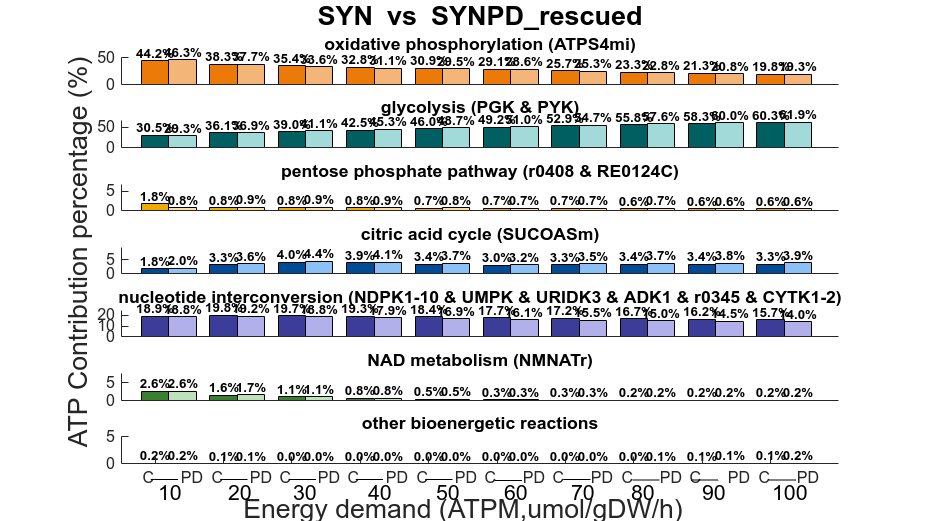

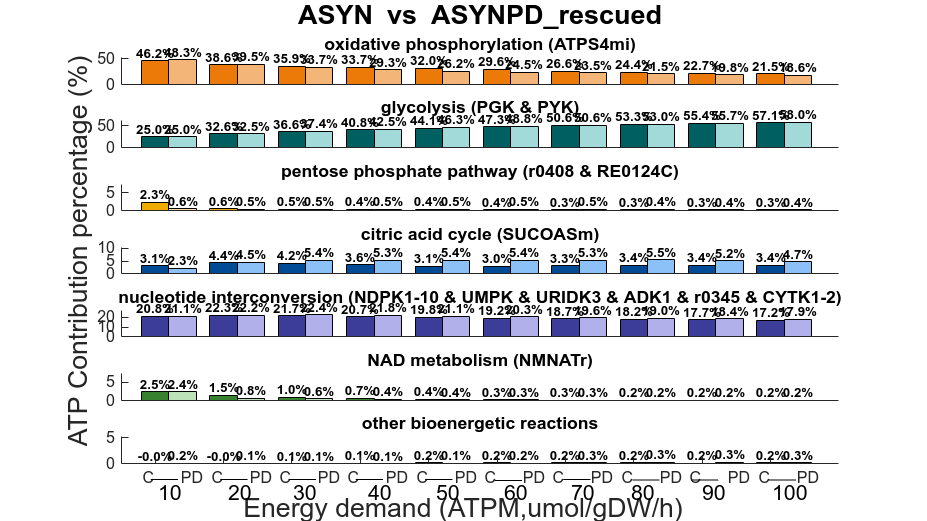

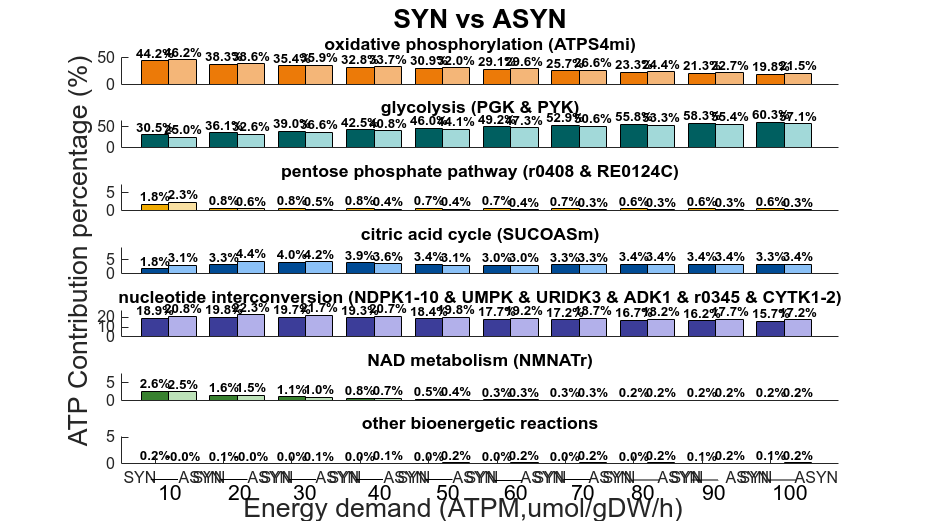

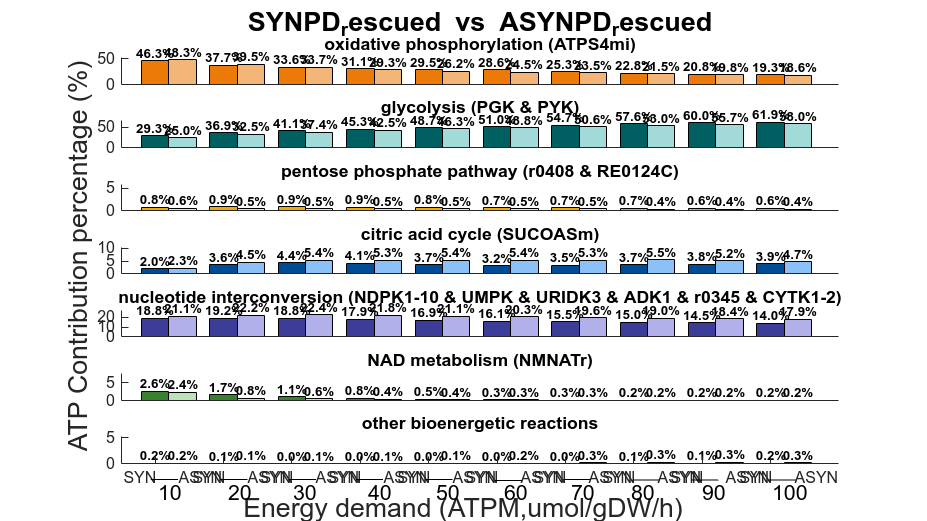

%% plot energy pattern under different ATPM
f='barchart';
plots_CandPD_v2(demandATP,f,d) % ATPM from 10-100